# Sampling with a uniform distribution in a Hypercube [0,1]* n

#### Latin Hypercube

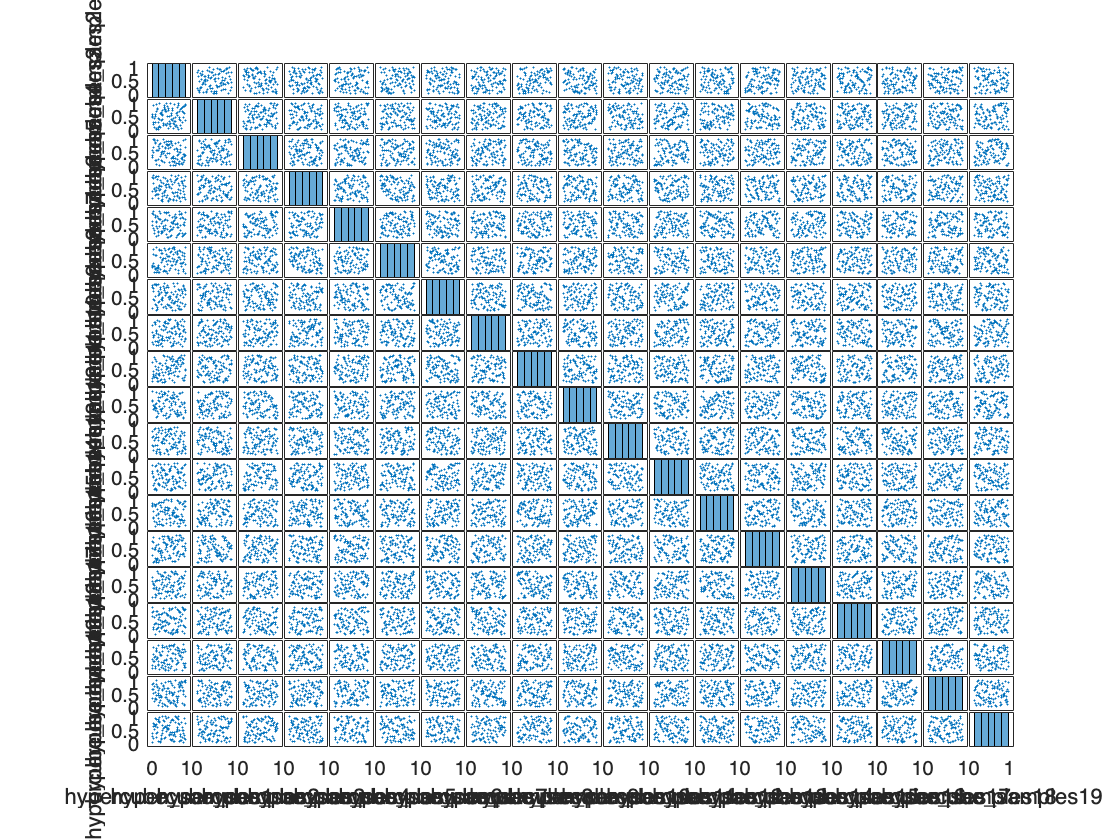

Range = [zeros(layer_num,1), ones(layer_num,1)]';
latin_hypercube_samples = UniformSampler(Range, layer_num, 1e2, 'LatinHypercube', true);

#### PseudoRandom Markov Chain

Range = [zeros(layer_num,1), ones(layer_num,1)]';
sobol_samples = UniformSampler(Range,  layer_num,  1e4,'Sobol', false);

function hypercube_samples = UniformSampler(range, N, samples, method, plotting)
    % UniformSampler Generates uniform samples in a hypercube.
    %
    %   hypercube_samples = UniformSampler(range, N, samples, method, plotting)
    %   generates uniform samples in an N-dimensional hypercube defined by
    %   the specified range. The method parameter determines the sampling
    %   technique, with options 'Sobol' (default) and 'LatinHypercube'.
    %
    %   Input Arguments:
    %       - range: A 2xN matrix defining the lower and upper bounds of the
    %                hypercube along each dimension.
    %       - N: The number of dimensions of the hypercube.
    %       - samples: (Optional) Number of samples to generate. Default is 10,000.
    %       - method: (Optional) Sampling method, 'Sobol' or 'LatinHypercube'.
    %                 Default is 'Sobol'.
    %       - plotting: (Optional) Logical flag indicating whether to plot
    %                   the generated samples. Default is false.
    %
    %   Output:
    %       - hypercube_samples: Generated uniform samples within the hypercube.
    %
    %   Examples:
    %       % Default usage with Sobol sequence
    %       samples = UniformSampler([0, 1; 2, 3], 2);
    %
    % If samples not specified, set it to 10,000
    if nargin < 3
        samples = 1e4;
    end
    
    % If method not specified, set it to Sobol
    if nargin < 4
        method = 'Sobol';
    end

    if nargin < 5
        plotting = false;
    end


    switch method
        case 'Sobol'
            p = sobolset(N);
            p = scramble(p,'MatousekAffineOwen');
            hypercube_samples = net(p, samples) .* (ones(samples, 1) * (range(2, :)-range(1, :)) ) + ones(samples, 1) * range(1, :);
        case 'LatinHypercube'
            hypercube_samples = lhsdesign(samples, N) .* ( ones(samples,1) * (range(2, :) - range(1, :)) ) + ones(samples, 1) * range(1, :);
    end

    if plotting
        sdo.scatterPlot(array2table(hypercube_samples))
    end
end